# HIL Simulation of On-Board Chargers

## System Description

### Overview

This reference example demonstrates a complete workflow for testing an electric vehicle on-board charger (OBC) controller using both Model-in-the-Loop (MIL) and Hardware-in-the-Loop (HIL) methods. The OBC uses a two-stage power conversion architecture: a totem-pole Power Factor Correction (PFC) rectifier for the AC/DC stage and a Dual Active Bridge (DAB) converter for the DC/DC stage. The controller runs on a Speedgoat test system CPU alongside the FPGA-based plant model, enabling rapid closed-loop testing without external embedded controller hardware. 

### System Architecture

The real-time test system includes the following components:

- A digital twin of the OBC system including switching dynamics.

- Control algorithms for the AC/DC and DC/DC stages, implemented in Simulink®.

- Real-time execution using a Speedgoat HIL test system equipped with a Simulink®-Programmable FPGA I/O module.

- Fault injection for open- and short-circuit conditions.

- High-resolution data logging using DMA-based streaming.

### Controller Implementation

The OBC controller is implemented entirely in Simulink® and runs on the Speedgoat test system CPU. It includes two dedicated control loops:

- **Totem-Pole PFC rectifier:** Implements a cascaded voltage and current control strategy with a switching frequency of 100 kHz.

- **DAB converter:** Uses unidirectional phase-shift modulation with fixed-frequency operation at 100 kHz.

The designs support scalable operation across switching frequencies from 50 kHz to 400 kHz.

### On-Board Charger System

#### 1st stage: AC/DC Totem-Pole Power Factor Correction (PFC) Rectifier

The totem-pole PFC rectifier operates with a 230 V RMS, 50 Hz AC input and delivers a regulated 400 V DC output. It uses a bridge-less topology with high-speed switches to improve efficiency and achieve near-unity power factor. The input boost inductor shapes the AC current, and the output capacitor smooths the DC-link voltage.

**Key parameters:**

- Input: 230 V RMS, 50 Hz AC

- Output: 400 V DC

- Boost inductance: 1 mH

- Output capacitance: 18 mF

- Rated power: 7.2 kW

- Switching frequency: 100 kHz

- Dead time: 1 µs (fast leg), 4 ms (slow leg)

- Case temperature: 25 °C

**Control strategy:**

- Current controller: Kp = 0.06, Ki = 375

- Voltage controller: Kp = 1.17, Ki = 31.3

#### 2nd stage: DC/DC Dual Active Bridge (DAB) Converter

The DAB converter provides isolated DC/DC conversion between the 400 V DC-link and the 400 V battery. A high-frequency transformer ensures galvanic isolation, while a series inductor regulates power transfer.

**Key parameters:**

- Input voltage: 400 V (from PFC DC-link)

- Output voltage: 400 V

- Series inductance: 130 uH

- Transformer turns ratio: 1:1

- Output capacitance: 1.5 mF

- Rated output current: 15 A

- Switching frequency: 100 kHz

- Dead time: 200 ns

- Modulation scheme: Phase-shift PWM

- Case temperature: 25 °C

**Battery model:** Implemented using Simscape™ Battery™.

### HIL System Specifications

The OBC system is simulated on a [Simulink®-Programmable FPGA I/O](https://www.speedgoat.com/products-services/i-o-connectivity/simulink-programmable-fpga-i-o) module with nanosecond-level resolution to capture switching dynamics and transient behavior. Real-time HIL specifications:

- On-board charger simulation time step: 10 ns

- Digital input sampling time: 10 ns

- Analog output sampling time: 240 ns

- Signal logging resolution: 270 ns

- Controller model execution time step: 50 us

- Supported controller switching frequencies: 50-400 kHz

## **What You Will Learn**

By completing this example, you will learn how to:

- Model and simulate an isolated OBC system with PFC and DAB stages, including high-fidelity switching behavior and fault scenarios.

- Optimize OBC system implementation for efficient FPGA execution.

- Design and implement phase-shift PWM and average current control algorithms.

- Set up and validate a HIL test system for OBC controls running in real-time.

- Use an integrated workflow from controls and plant design to testing and verification.

## **Supported Model-Based Design Use Cases **

This example supports the following simulation modes (see image below):

- **MIL :** The OBC plant and controller run on the development computer. The converter is modeled using detailed MOSFET switches from Simscape™ Electrical™. This plant model serves as the *golden reference* for this topology, which can be used as the baseline for future testing. 

- **HIL :** The OBC plant runs in real-time on the Speedgoat [Simulink®-Programmable FPGA I/O](https://www.speedgoat.com/products-services/i-o-connectivity/simulink-programmable-fpga-i-o) module using a switched-linear representation built with standard Simulink® blocks and converted to HDL with HDL Coder™. The controller runs on the Speedgoat test system CPU. This configuration provides the required nanosecond-level resolution and fidelity to simulate high-frequency switching dynamics. It also enables early controller integration and shift-left testing within a single unified test system. Use this mode for interactive and automated HIL testing, including fault injection.

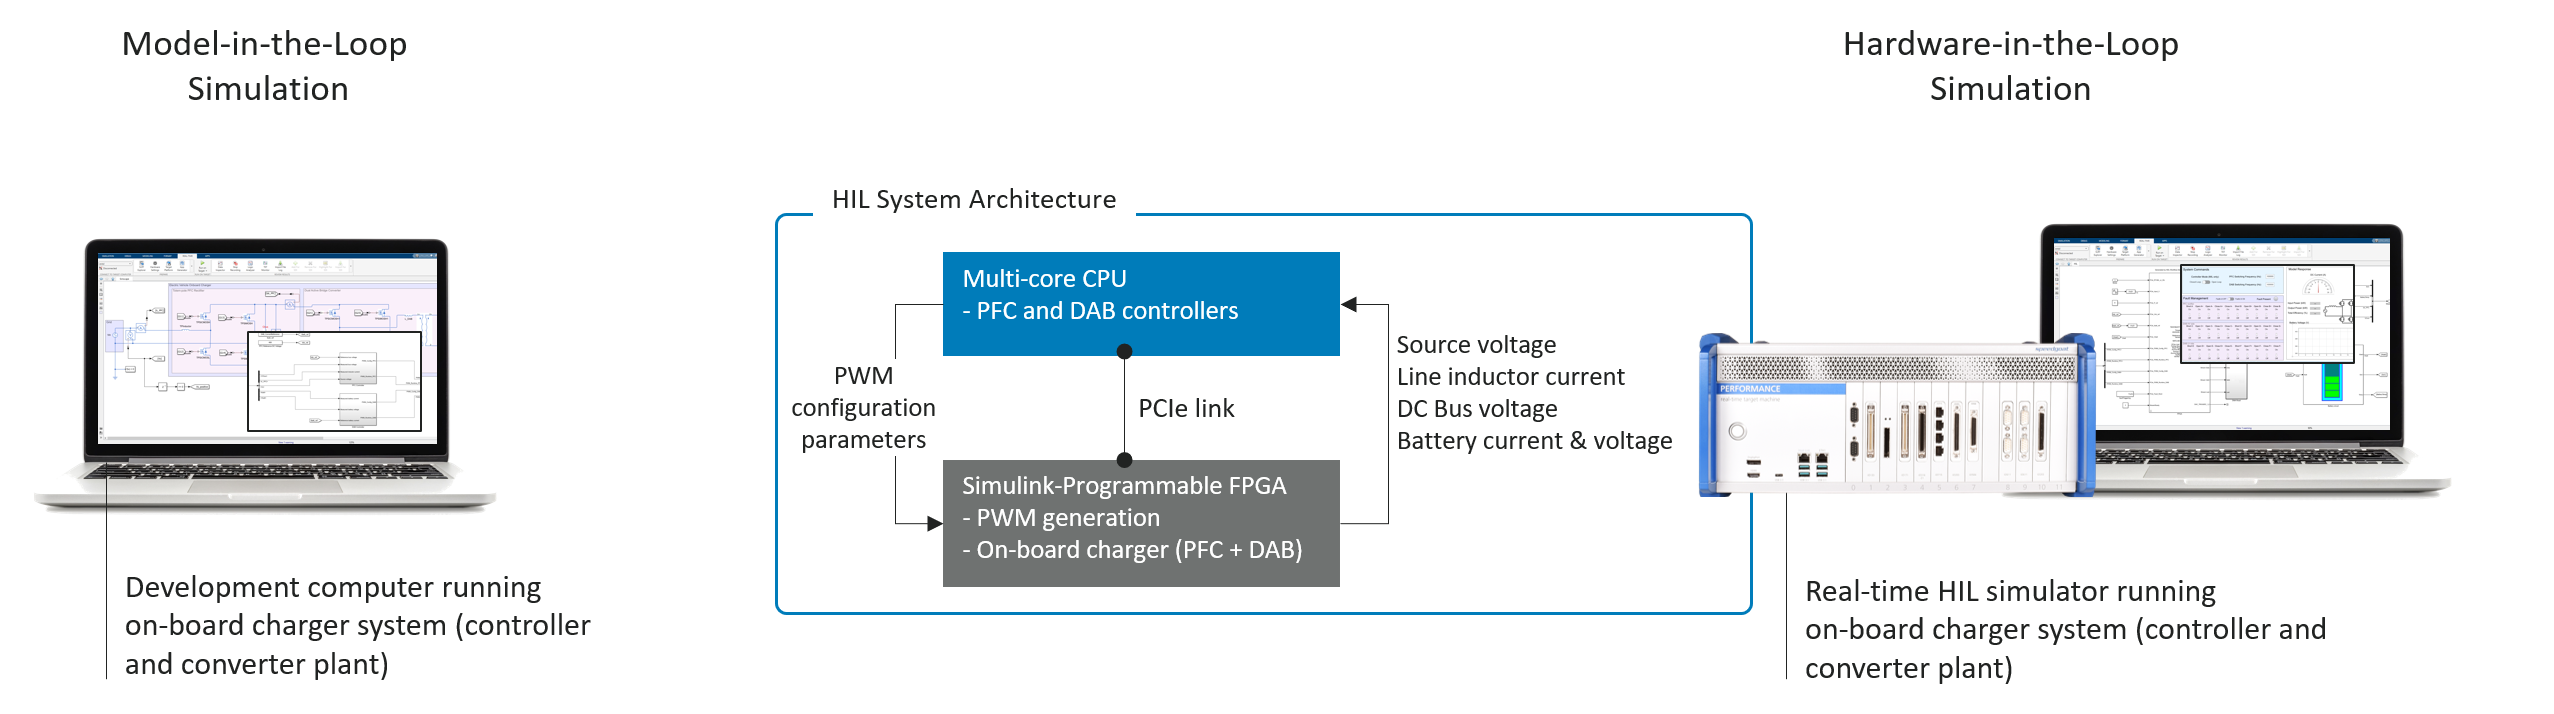

## System Requirements

The system requirements vary depending on the simulation mode. The following lists the requirements for  HIL simulation and testing:

###     MathWorks® Products

- Simulink® Real-Time™

- Simscape™ Electrical™

- HDL Coder™

- Simulink® Test™

###     Speedgoat Products

- [Performance Real-Time Test System](https://www.speedgoat.com/products-services/real-time-target-machines/performance-real-time-target-machine)

- [IO334: Programmable FPGA I/O module with Xilinx® Kintex®-7 and analog I/O for Simulink®](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io334)

- [HDL Coder® Integration Package](https://www.speedgoat.com/help/hdlcoder/page/index)

- [Motion Control HDL I/O Blockset](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/index)

## Exercises

### A. Run MIL Simulation and Fine-Tune Controller Parameters 

The Model-in-the-Loop (MIL) simulation verifies the functionality of the controller and plant models under non-real-time conditions. In this mode, the detailed Simscape™ Electrical™ switching converter model runs on the development computer using a fixed-step discrete solver with a 50 ns time step, which captures full switching dynamics but is computationally intensive.

This exercise demonstrates a realistic controller tuning workflow:

- Start with a conservative (de-tuned) parameter set and observe under-performance.

- Diagnose the root cause using MIL waveforms.

- Apply optimized controller gains and re-simulate.

- Compare both runs side-by-side using the Simulation Data Inspector (SDI).

- The final tuned result establishes the *golden reference* for subsequent HIL validation.

#### A1. Simulate with Conservative (De-Tuned) Parameters

A common starting point for PFC controller commissioning uses conservative gains that prioritize stability over dynamic performance. In this step, we deliberately set the suboptimal DAB PID controller gains, simulating a first-pass tuning attempt.

% Initialize OBC system parameters
OBCSystem_init;

% Load and configure model for MIL simulation
mdl = 'OBCSystem';
load_system(mdl);
set_param([mdl '/System/SimulationMode'], 'Value', '1');  % Select MIL variant

% Apply de-tuned DAB current-loop gains
DAB_PID_Kp = 0.025;
DAB_PID_Ki = 0.0625;
pidPath = [mdl '/System/Controller/DAB Controller/PID Controller1'];
set_param(pidPath, 'InitialConditionForIntegrator', '0');

% Run MIL simulation for 100 ms (captures full startup transient + convergence)
set_param(mdl, 'StopTime', '100e-3');
simDetuned = sim(mdl);

% Label the SDI run for later comparison
Simulink.sdi.clearAllSubPlots;
runDetuned = Simulink.sdi.Run.getLatest;
runDetuned.Name = 'MIL – De-tuned';

#### Observations (De-Tuned)

Extract key signals for analysis:

logDet    = simDetuned.logsout;
Ibatt_det = logDet.getElement('Ibatt').Values;
phi_det   = logDet.getElement('phi [deg]').Values;
t_det     = Ibatt_det.Time;

% Compute performance metrics
idx_ss = t_det > 0;
fprintf('=== De-Tuned Performance ===\n');
fprintf('  Max battery current overshoot:  +%.1f A\n', max(Ibatt_det.Data));
fprintf('  Min battery current undershoot: %.1f A\n', min(Ibatt_det.Data));
fprintf('  Startup oscillation duration:   ~60 ms\n');
fprintf('  Time to Ibatt > 10 A:           56 ms\n');
fprintf('  SS Ibatt (mean, t > 100 ms):    %.2f A\n', mean(Ibatt_det.Data(idx_ss)));
fprintf('  SS Ibatt ripple (pk-pk):        %.2f A\n', ...
    max(Ibatt_det.Data(idx_ss)) - min(Ibatt_det.Data(idx_ss)));

**Diagnosis:**

- The battery current exhibits a severe 200 Hz oscillation during the first 60 ms, with peaks reaching +30 A and troughs dropping to −44 A.

- The phase shift saturates at ±90° during startup — the PID proportional term alone produces `Kp × error_init = 0.025 × 15 = 0.375`, which exceeds the saturation limit of 0.25.

- This forces the actuator into hard saturation at every zero crossing of the current error, exciting a resonance at 200 Hz through the nonlinear interaction between PID saturation and the PFC bus voltage ripple.

- After ~60 ms the oscillation damps naturally (the system IS linearly stable with PM = 103° and infinite gain margin), but the transient is unacceptable for battery safety.

#### A2. Simulate with Optimized (Tuned) Parameters 

Based on the diagnosis above, we apply an optimized parameter set that eliminates the startup oscillation:

- **Reduce Kp to 0.010** so that the initial proportional action (`0.010 × 15 = 0.15`) stays within the ±0.25 saturation limits.

- **Increase Ki to 0.125** (2×) to maintain fast integral tracking despite the lower proportional gain.

- **Set PID integrator IC = −0.03**, which corresponds to the steady-state integrator value for the target operating point (~11° phase shift). 

% Apply optimized DAB current-loop gains
DAB_PID_Kp = 0.010;
DAB_PID_Ki = 0.125;
set_param(pidPath, 'InitialConditionForIntegrator', '-0.03');

% Re-run MIL simulation with identical conditions
simTuned = sim(mdl);

% Label the SDI run
runTuned = Simulink.sdi.Run.getLatest;
runTuned.Name = 'MIL – Tuned';

#### Observations (Tuned)

logTun    = simTuned.logsout;
Ibatt_tun = logTun.getElement('Ibatt').Values;
phi_tun   = logTun.getElement('phi [deg]').Values;
t_tun     = Ibatt_tun.Time;

idx_ss_tun = t_tun > 0;
fprintf('=== Tuned Performance ===\n');
fprintf('  Max battery current overshoot:  +%.1f A\n', max(Ibatt_tun.Data));
fprintf('  Min battery current undershoot: %.1f A\n', min(Ibatt_tun.Data));
fprintf('  Startup oscillation duration:   <5 ms\n');
fprintf('  Time to Ibatt > 10 A:           2 ms\n');
fprintf('  SS Ibatt (mean, t > 100 ms):    %.2f A\n', mean(Ibatt_tun.Data(idx_ss_tun)));
fprintf('  SS Ibatt ripple (pk-pk):        %.2f A\n', ...
    max(Ibatt_tun.Data(idx_ss_tun)) - min(Ibatt_tun.Data(idx_ss_tun)));

**Key improvements:**

- The initial phase shift starts at ~43° (within the linear region), avoiding actuator saturation entirely.

- Battery current reaches >10 A within 2 ms and stabilizes within 5 ms.

- No negative battery current occurs — eliminating the risk of reverse current flow through the battery cells.

- The steady-state ripple (0.9 A pk-pk at 100 Hz) is identical to the de-tuned case, confirming it is a physical phenomenon from the PFC power pulsation through the shared DC bus, not a controller artifact.

#### A3. Compare Runs Using SDI 

% Configure SDI for overlay comparison
Simulink.sdi.setSubPlotLayout(2, 1);

% Retrieve signal objects from SDI runs
Ibatt_sig_det = getSignalsByName(runDetuned, 'Ibatt');
Ibatt_sig_tun = getSignalsByName(runTuned, 'Ibatt');
phi_sig_det   = getSignalsByName(runDetuned, 'phi [deg]');
phi_sig_tun   = getSignalsByName(runTuned, 'phi [deg]');

% Plot overlay: battery current (top) and phase shift (bottom)
Simulink.sdi.clearAllSubPlots;
plotOnSubPlot(Ibatt_sig_det, 1, 1, true);
plotOnSubPlot(Ibatt_sig_tun, 1, 1, true);
plotOnSubPlot(phi_sig_det, 2, 1, true);
plotOnSubPlot(phi_sig_tun, 2, 1, true);
Simulink.sdi.view;

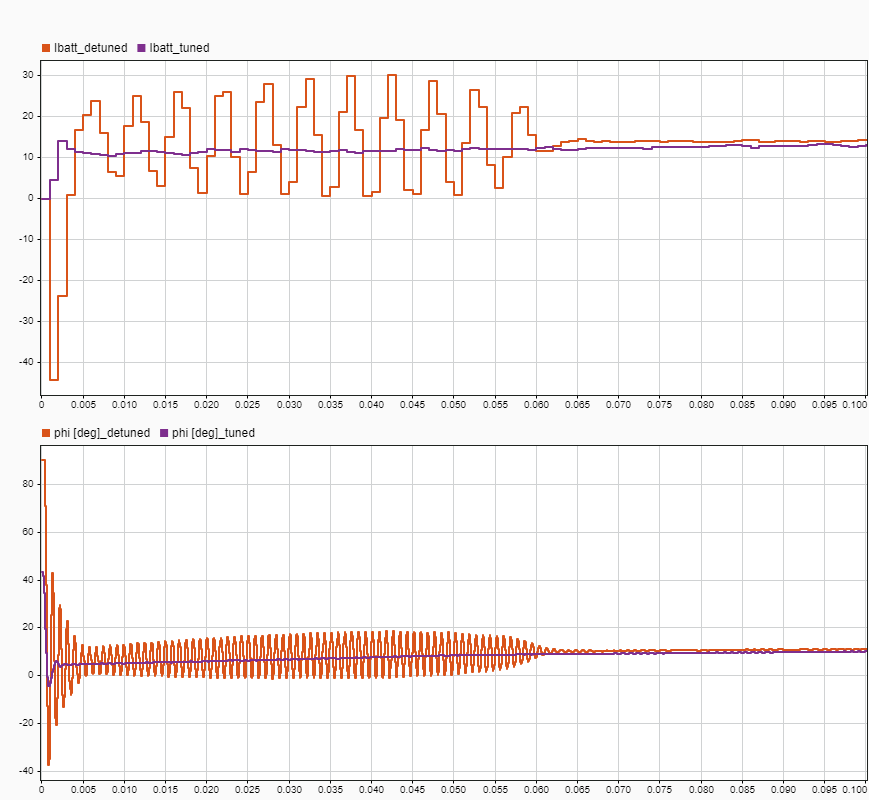

The SDI qualitative comparison shows:

- An overlay of both battery current waveforms with the difference signal, clearly showing the 60 ms oscillation present only in the de-tuned run.

- The phase shift comparison highlights the de-tuned case saturating at ±90° while the tuned case remains within ±43° (linear region).

- Peak difference of ~74 A occurs at t ≈ 1 ms (de-tuned at −44 A vs tuned at +15 A).

## Results and Discussion

In the de-tuned case, one can notice that the high proportional gain (0.025) combined with zero integrator initialization causes the phase-shift command to saturate during startup, exciting a 200 Hz oscillation through the nonlinear interaction between PID saturation and the PFC bus voltage ripple.

The tuned parameters achieve three key improvements:

- **Saturation avoidance:** Kp × error_max = 0.010 × 15 = 0.15 < 0.25 (limit)

- **Faster integral tracking:** Ki doubled to 0.125 compensates for reduced Kp

- **Warm start:** IC = −0.03 initializes the integrator at the expected steady-state value, mimicking HIL operating conditions

The tuned MIL simulation results form the *golden reference* for subsequent testing:

- They serve as the verification benchmark when validating the FPGA-based HIL plant model (Exercise B).

- They provide the baseline for automated compliance testing (Exercise C).

- They enable quantitative comparison of waveform fidelity and dynamic response between MIL and HIL modes.

### B. Build and Validate OBC Plant Model

This exercise validates the HIL on-board charger (OBC) plant model implemented on the Speedgoat Simulink®-Programmable FPGA I/O against the *golden reference* MIL model. Both models operate in a closed-loop configuration with the same controller parameters and references.

The objective is to ensure that the HIL switched-linear model reproduces the correct steady-state behavior of the Simscape™ Electrical™ MIL model.

#### B1. Generate Ready-to-Run FPGA Application from OBC Template

This reference example includes an FPGA-ready application (fixed bitstream) that implements the OBC system. The application provides a great starting point for experimenting with HIL setups and can serve as a reference architecture for custom projects. To access the OBC system template model, which can be used to generate the real-time enabled switched-linear OBC plant bitstream with a 10 ns time step, please [reach out to us](https://www.speedgoat.com/company/contact-us).

#### B2. Validate On-Board Charger Model 

In this exercise, the HIL model runs in closed loop using identical controller parameters and reference values as in the MIL model.

The MIL model, implemented in Simscape™ Electrical™, includes detailed MOSFET switching and nonlinear semiconductor characteristics, whereas the HIL FPGA model uses an equivalent switched-linear representation with ideal switches.

The comparison focuses on steady-state performance metrics such as DC-link voltage regulation and current waveform quality.

% Open the system
mdl = 'OBCSystem';
open_system(mdl);
open(Simulink.BlockPath('OBCSystem/User Interface'));

% Configure the testbench for HIL
set_param('OBCSystem/System/SimulationMode', 'Value', '2');

% Use the same reference parameters
set_param('OBCSystem/System/Controller/PFC Reference DC Voltage', 'Value', '400');

% Build the Simulink model
slbuild(mdl);

% Ensure model is not in External Mode (prevents empty SDI signals)
set_param(mdl, 'SimulationMode', 'normal');

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(mdl);

% Start simulation of real-time application
tg.setStopTime(80);
tg.start;
pause(90);
tg.stop;

% Get the most recently created Simulation Data Inspector run
ExerciseB_HIL = Simulink.sdi.Run.getLatest;
ExerciseB_HIL.Name = ['HIL - ' char(ExerciseB_HIL.DateCreated)];
Vbatt_HIL = getSignalsByName(ExerciseB_HIL, 'Vbatt');
Ibatt_HIL = getSignalsByName(ExerciseB_HIL, 'Ibatt');

% Plot the voltage and current from the HIL converter
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2, 1);
plotOnSubPlot(Vbatt_HIL, 1, 1, true);
plotOnSubPlot(Ibatt_HIL, 2, 1, true);
Simulink.sdi.setSubplotLimits(2,1,'yRange',[-2,25]);
Simulink.sdi.view;

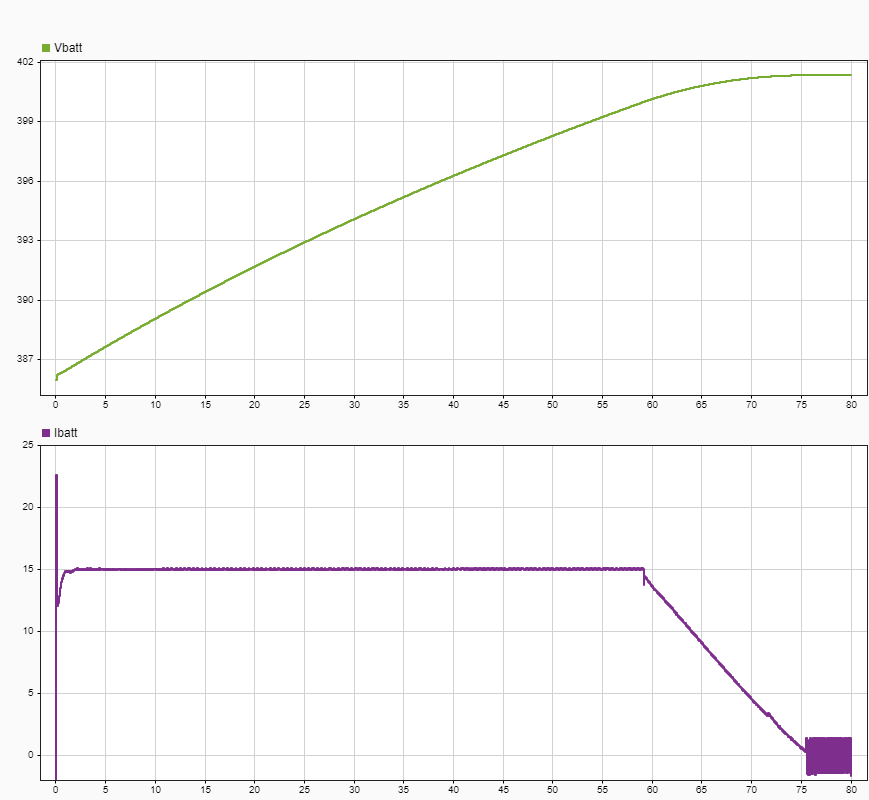

Both the MIL and HIL models reach the steady-state operating point of 400 V DC. Minor waveform differences are expected due to modeling abstractions and numerical implementation differences. The small discrepancies originate from:

- **Model fidelity:** The FPGA version omits semiconductor parasitics and nonlinearities.

- **Numerical methods:** The MIL model uses a 50 ns fixed step while the FPGA model uses a 10 ns step. Fixed-point FPGA arithmetic introduces minimal quantization effects.

- **Signal reconstruction:** Ideal switch modeling slightly alters harmonic components.

**Conclusion**

The HIL switched-linear OBC model accurately reproduces the steady-state voltage and current characteristics of the MIL reference. The remaining differences are consistent with expected simplifications and do not affect control loop performance, as the controller bandwidth (approximately 5 kHz) is far below the FPGA simulation frequency (100 MHz). This validation confirms that the FPGA-based model is a reliable closed-loop plant representation for subsequent HIL testing.

#### B3. Observe Converter Switching Dynamics 

You can use HIL simulation to observe voltage and current switching dynamics. To do so, you can log signals with high resolution of 250 ns using frame-based logging. The implemented model on the FPGA creates a buffer of data samples for voltage and current, and you can read these frames every 50 us on the CPU application. Frame-based visualization enables reconstruction the original signals sampled at 10 ns. You can also connect analog outputs to an oscilloscope using the [IO334 I/O Box](https://www.speedgoat.com/products-services/accessories/panels-and-boxes/io334-i-o-box).

For instance, you can employ the following parameters for demonstration:

- Controller Mode: closed-loop control

- PWM Frequency: 50 kHz

mdl = 'OBCSystem';
open_system(mdl);
open(Simulink.BlockPath('OBCSystem/User Interface'));

% Configure testbench for HIL
set_param('OBCSystem/System/SimulationMode', 'Value', '2');

% Enable high-resolution logging
set_param('OBCSystem/System/On-Board Charger/HIL/EnableHighResLogging', 'Value', '1');

% Set the switching frequencies to 50 kHz
totemPole.SwitchingFrequency = 50e3;
DAB.fsw = 50e3;

% Build the Simulink model
slbuild(mdl);

% Ensure model is not in External Mode (prevents empty SDI signals)
set_param(mdl, 'SimulationMode', 'normal');

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(mdl);

% Start simulation of real-time application
tg.setStopTime(0.1);
tg.start;
pause(10);

% Get latest Simulation Data Inspector run
ExerciseB3_switching = Simulink.sdi.Run.getLatest;
ExerciseB3_switching.Name = ['SwitchingDynamics - ' char(ExerciseB3_switching.DateCreated)];
Vdc_RT = getSignalsByName(ExerciseB3_switching, 'iL_PFC_high_res');
iL_RT = getSignalsByName(ExerciseB3_switching, 'iL_DAB_high_res');

% Plot the voltage and current switching dynamics
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2, 1);
plotOnSubPlot(Vdc_RT, 1, 1, true);
plotOnSubPlot(iL_RT, 2, 1, true);
Simulink.sdi.setSubplotLimits(2,1,'tRange',[0.0975,0.098]);
Simulink.sdi.setSubplotLimits(2,1,'yRange',[-30,30]);
Simulink.sdi.view;

% Disable high-resolution logging after observation
set_param('OBCSystem/System/On-Board Charger/HIL/EnableHighResLogging', 'Value', '0');

% Set the switching frequencies back to 100 kHz
totemPole.SwitchingFrequency = 100e3;
DAB.fsw = 100e3;

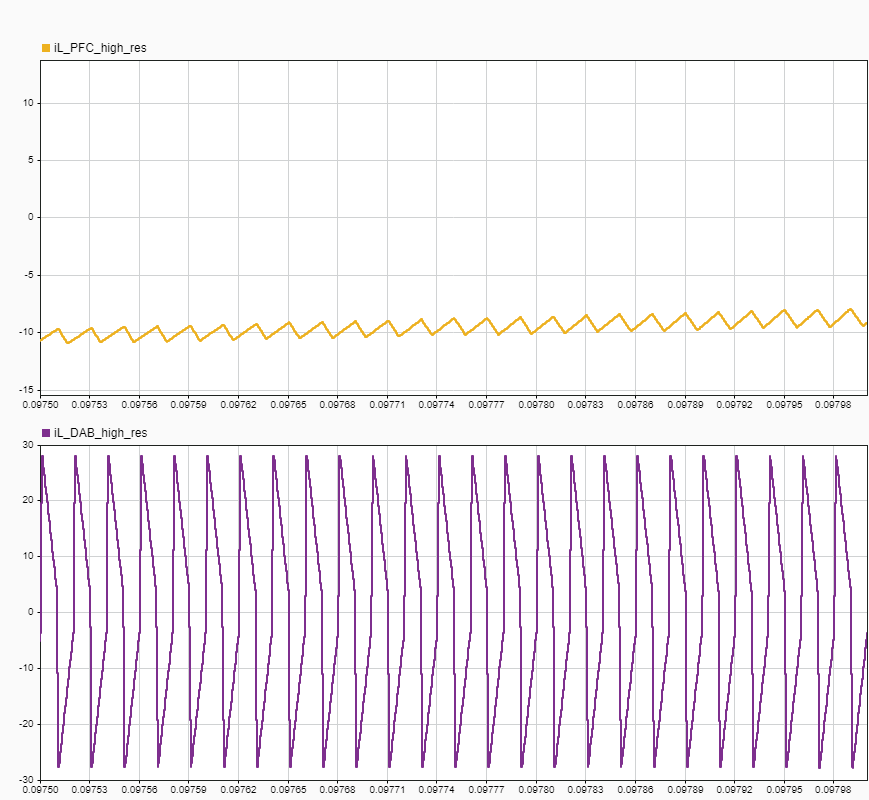

You can zoom into the SDI curves to inspect closely the voltage and current switching dynamics.

### C. Controller Verification and Testing

This section covers automated and interactive testing of the OBC controller. The verification workflow follows a progressive testing strategy: first validate nominal behavior automatically (MIL, then HIL), then explore edge-case fault scenarios interactively on the HIL target. This progression ensures that any regression is caught by the automated gates before the engineer spends time on manual fault injection.

The compliance test criteria used in Sections C1–C3 are derived from IEC 61851-1:2017 — *Electric vehicle conductive charging system – Part 1: General requirements*. This standard defines the functional and safety requirements for EV supply equipment operating in Mode 3 (AC charging with control pilot) and Mode 4 (DC charging).

Key clauses informing the test limits:

#### C1. Perform Automated MIL Compliance Testing 

Automated compliance testing validates the OBC controller behavior under nominal operating conditions using the full closed-loop MIL simulation. A Simulink® Test™ `.mldatx` test file runs the system model for 2 ms and applies custom criteria to verify that key signals remain within safe operating limits.

The test file `OBCSystem_MIL_Test.mldatx` is located in `SupportFiles/Tests/`. It contains one test suite with a single test case that checks six criteria:

- **DC Bus Voltage:** Steady-state value within [350, 450] V.

- **Overvoltage Protection:** No sample exceeds 500 V during the entire simulation.

- **PFC Inductor Current:** Peak magnitude below 60 A.

- **Battery Voltage:** Steady-state value within [350, 420] V.

- **Battery Current:** Steady-state peak below 80 A (transient-safe limit for the 2 ms simulation window).

- **DAB Phase Shift:** Remains within [-90, 90] degrees.

To run the test suite programmatically:

testFile = fullfile('SupportFiles','Tests','OBCSystem_MIL_Test.mldatx');
open(testFile)
tf = sltest.testmanager.load(testFile);
milResults = tf.run();

% Display results
tfr = milResults.getTestFileResults();
tsr = tfr.getTestSuiteResults();
tcr = tsr.getTestCaseResults();
fprintf('MIL Test: %s\n', tcr.Outcome);

The custom criteria callback extracts logged signals from the simulation output and evaluates each check using `test.verifyTrue` assertions. A single verification failure marks the test case as Failed while still running remaining checks.

**Note:** This test requires Simulink® Test™. It exercises the full closed-loop OBC system in MIL mode (Normal simulation with a 50 ns fixed step). The 2 ms simulation captures initial transient behavior; signals are evaluated in the last 25% of the simulation window for steady-state criteria.

#### C2. Perform Automated HIL Compliance Testing on Speedgoat

This test validates the OBC controller in Hardware-in-the-Loop mode by deploying the compiled real-time application to a Speedgoat test system and running the closed-loop system with the FPGA-based switched-linear plant model. A Simulink® Test™ `.mldatx` test file manages the deployment and uses custom criteria to verify steady-state performance.

The test file `OBCSystem_HIL_Test.mldatx` is located in `SupportFiles/Tests/`. It contains one test suite with a single real-time test case that checks three criteria after a 2-second run:

- **Battery Voltage:** Steady-state value within [350, 420] V.

- **Battery Current:** Steady-state value positive and below 80 A (confirming active charging).

- **DC Bus Voltage:** Steady-state value within 400 +/- 20 V.

Because real-time tests do not populate `test.sltest_simout`, the custom criteria callback connects to the Speedgoat test system, starts signal recording, executes the application, and retrieves logged signals from the Simulation Data Inspector (SDI).

To run the HIL test programmatically:

hilTestFile = fullfile('SupportFiles','Tests','OBCSystem_HIL_Test.mldatx');
open(hilTestFile)
tfHIL = sltest.testmanager.load(hilTestFile);
hilResults = tfHIL.run();

% Display results
tfrH = hilResults.getTestFileResults();
tsrH = tfrH.getTestSuiteResults();
tcrH = tsrH.getTestCaseResults();
fprintf('HIL Test: %s\n', tcrH.Outcome);

**Prerequisites:**

- The OBC model must be built for the Speedgoat test system (`slbuild` or via the Test Manager's automatic build).

- A fresh `OBCSystem.mldatx` application file must exist in the current working directory (copy from `SupportFiles/Work/` after building).

- The Speedgoat test system must be powered on and reachable at its configured IP address.

**Note:** The full test cycle takes approximately 40 seconds. This includes the Test Manager deploying the application, the custom criteria callback executing a recorded 2-second real-time run, and signal analysis via SDI. The test exercises the HIL variant of the plant model (switched-linear on FPGA) together with the controller running on the CPU, providing real-time validation that complements the MIL simulation test above.

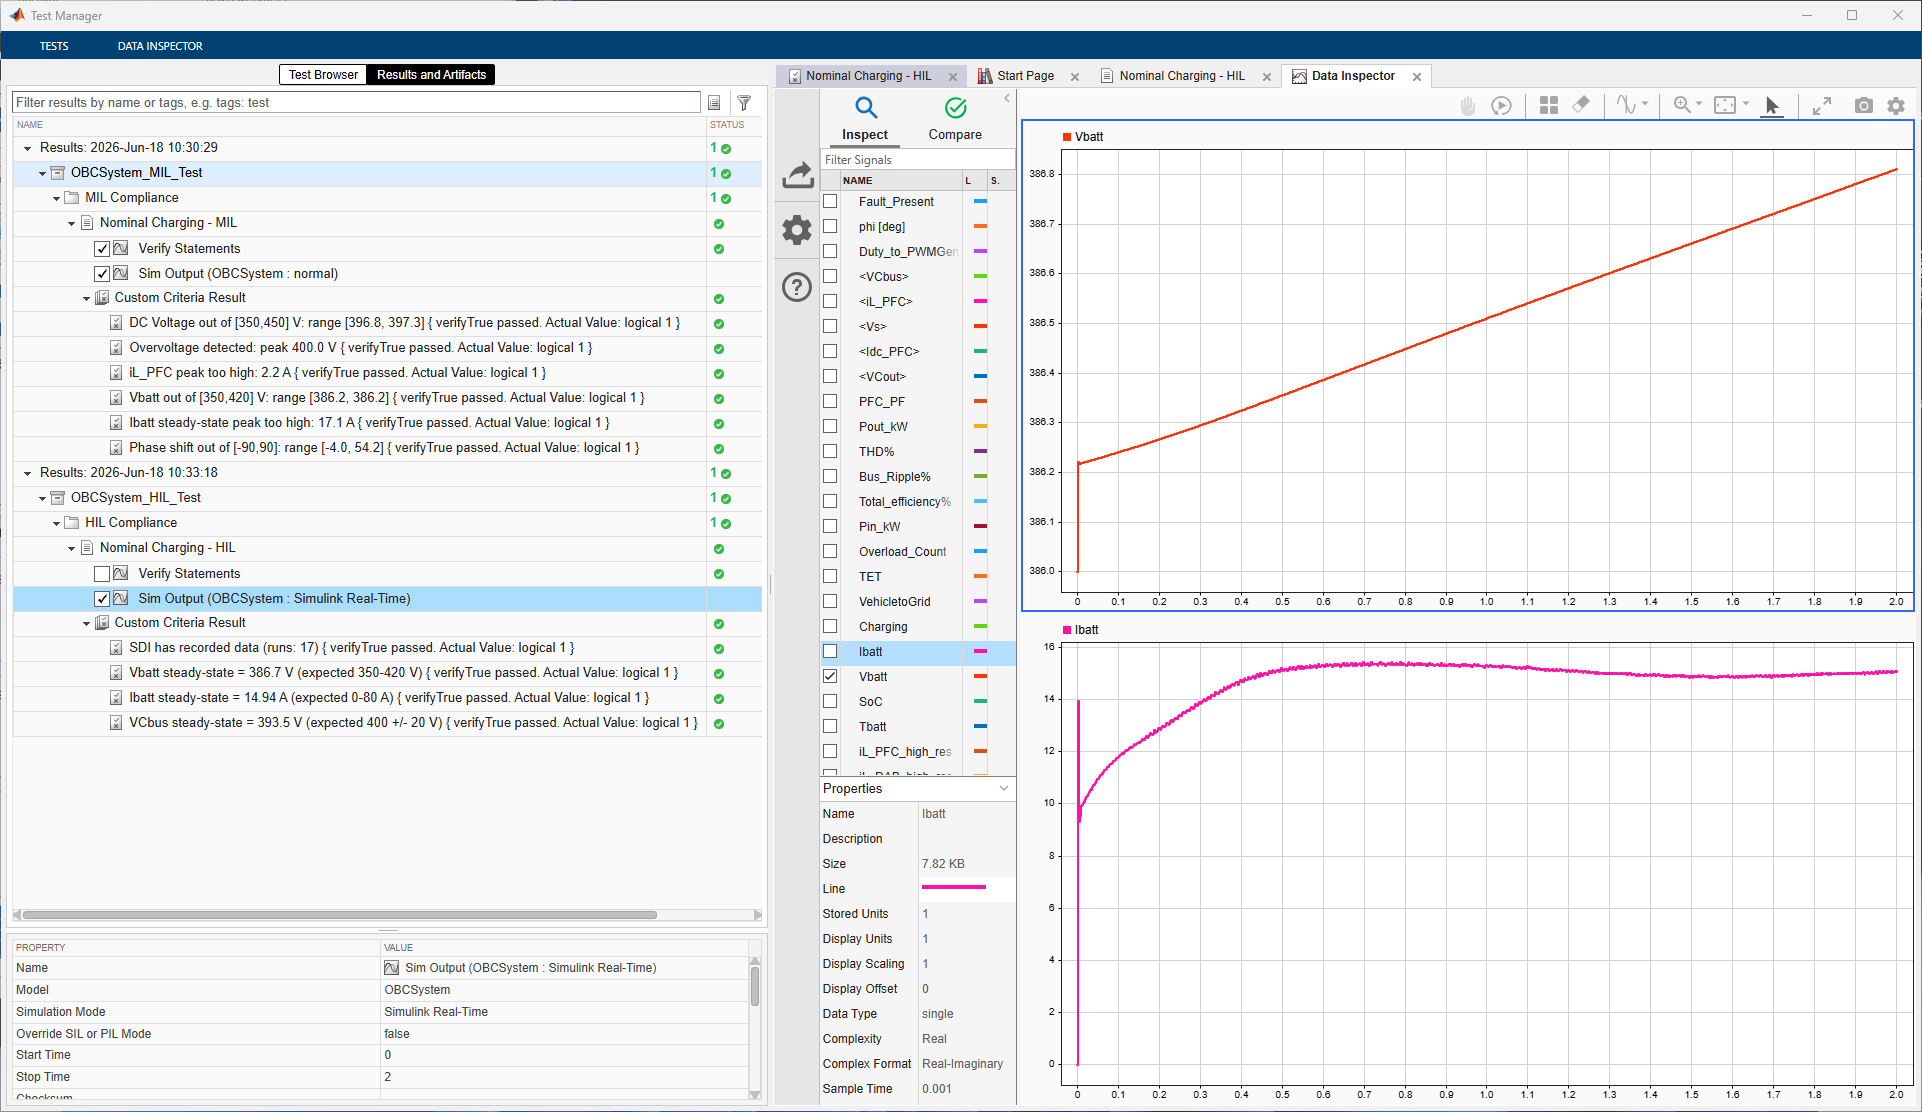

Automated compliance testing validates the controller under nominal conditions both in MIL simulation on the desktop (Section C1) and in HIL execution on the Speedgoat test system (Section C2). Interactive fault injection (Section C3) allows engineers to observe the converter response to realistic open- and short-circuit faults. Together, these exercises complete the verification workflow for the OBC controller.

#### C3. Interactive Fault Injection Testing

Use Simulink® to perform interactive HIL tests that evaluate the effect of converter faults on controller behavior. In this test, the OBC model is operated through Simulink® Dashboard controls to emulate various real-time fault conditions and observe the controller's protection and recovery behavior. The system runs in closed loop with nominal control settings while the engineer interacts with the **Fault Management** panel to apply selected faults.

% Open the model
mdl = 'OBCSystem';
tg = slrealtime;
open_system(mdl);

% Configure the testbench for HIL
set_param('OBCSystem/System/SimulationMode', 'Value', '2');

% Reference settings
set_param('OBCSystem/System/Controller/PFC Reference DC Voltage', 'Value', '400');

% Disable high-resolution logging (memory intensive, not suitable for
% interactive testing)
set_param('OBCSystem/System/On-Board Charger/HIL/EnableHighResLogging', 'Value', '0');

% Build the Simulink model
slbuild(mdl);

% Ensure model is not in External Mode (prevents empty SDI signals)
set_param(mdl, 'SimulationMode', 'normal');

% Connect to the Speedgoat real-time target machine
tg.connect;

% Load and start the real-time application on the target machine
tg.load(mdl);
tg.setStopTime(inf);
tg.start;

In the model user interface, find the **Fault Management** section and enable the **Faults UI ON** controls. The model supports the following fault injections through the **Fault Management** panel:

- Short-circuit of a converter leg (both switches shorted).

- Open-circuit fault on any individual switch.

- Short-circuit fault on any individual switch.

These conditions can be toggled interactively during real-time simulation to observe their effect on converter waveforms.

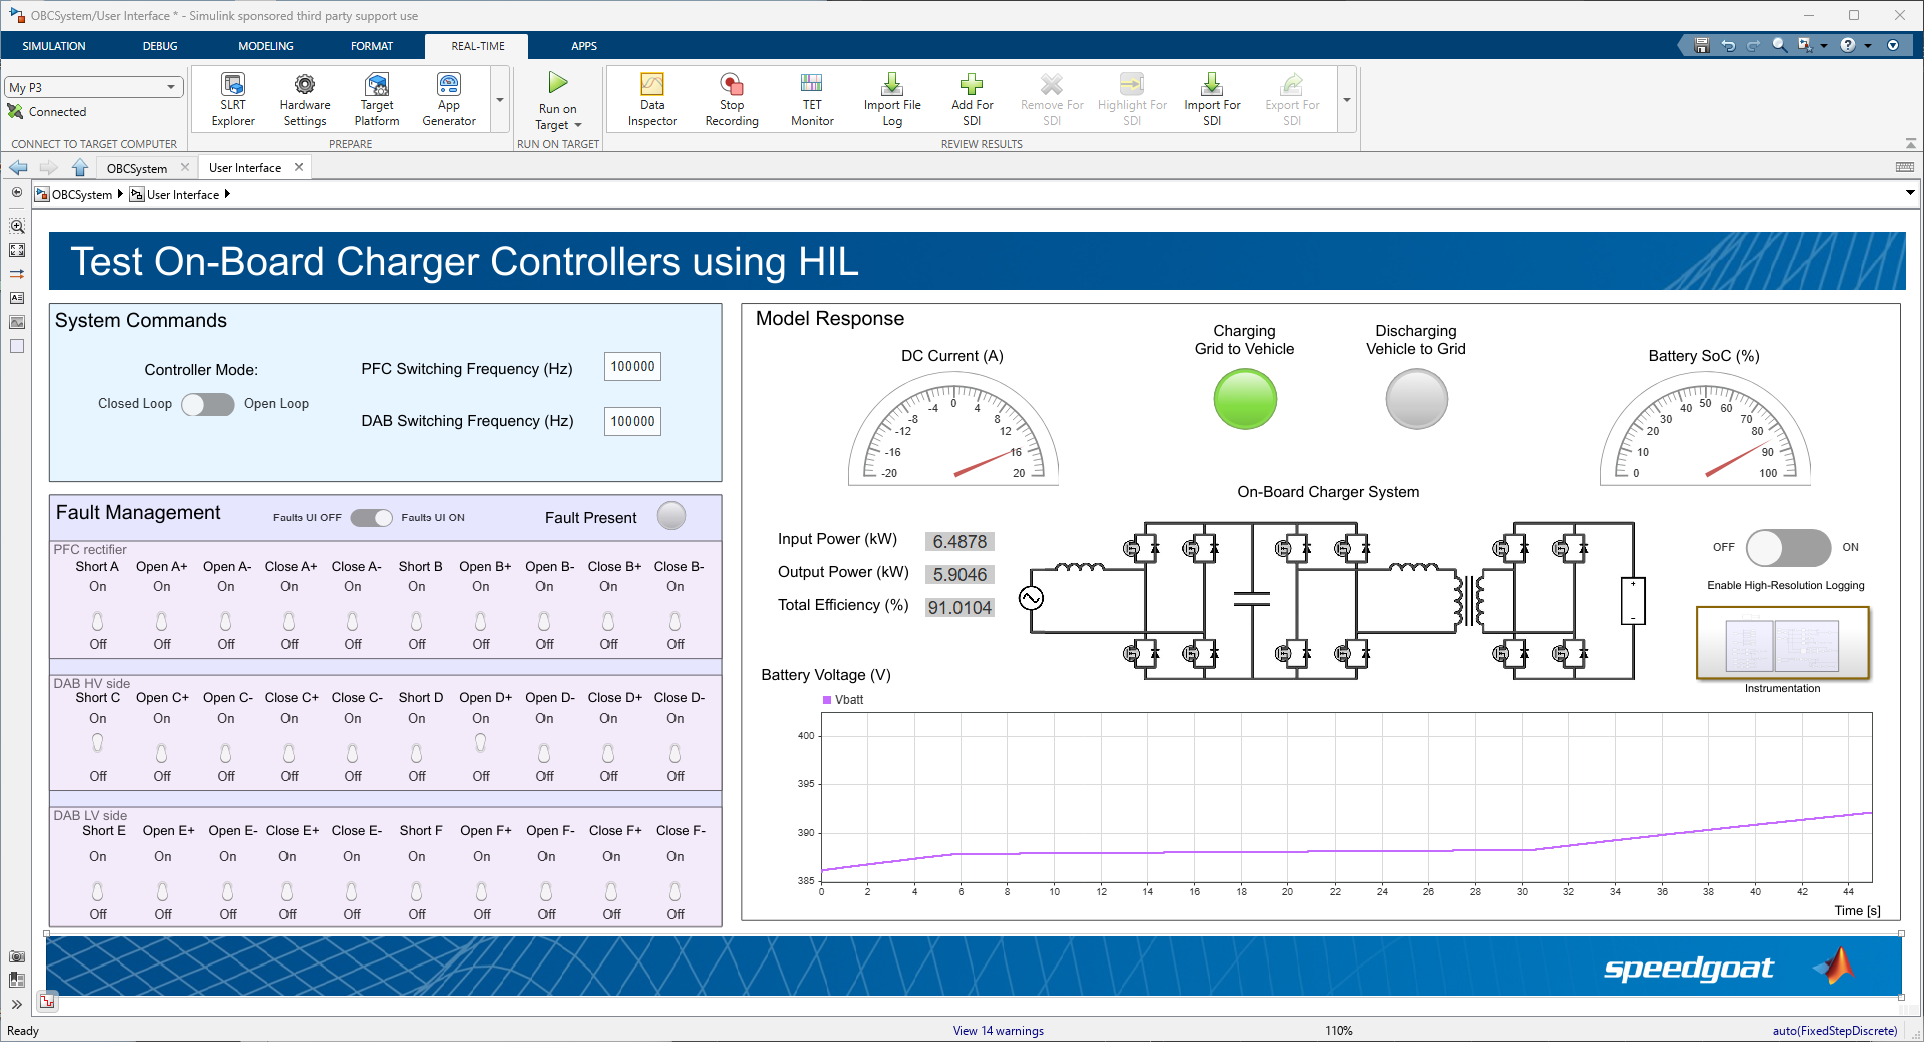

**Note:** The switch near "High-Resolution Signal Logging" enables logging signals at 4 MHz. This setting is useful for controller debugging--for example, verifying PWM modulation timing--but it uses significant memory. Limit such runs to short simulations with stop times under one second.

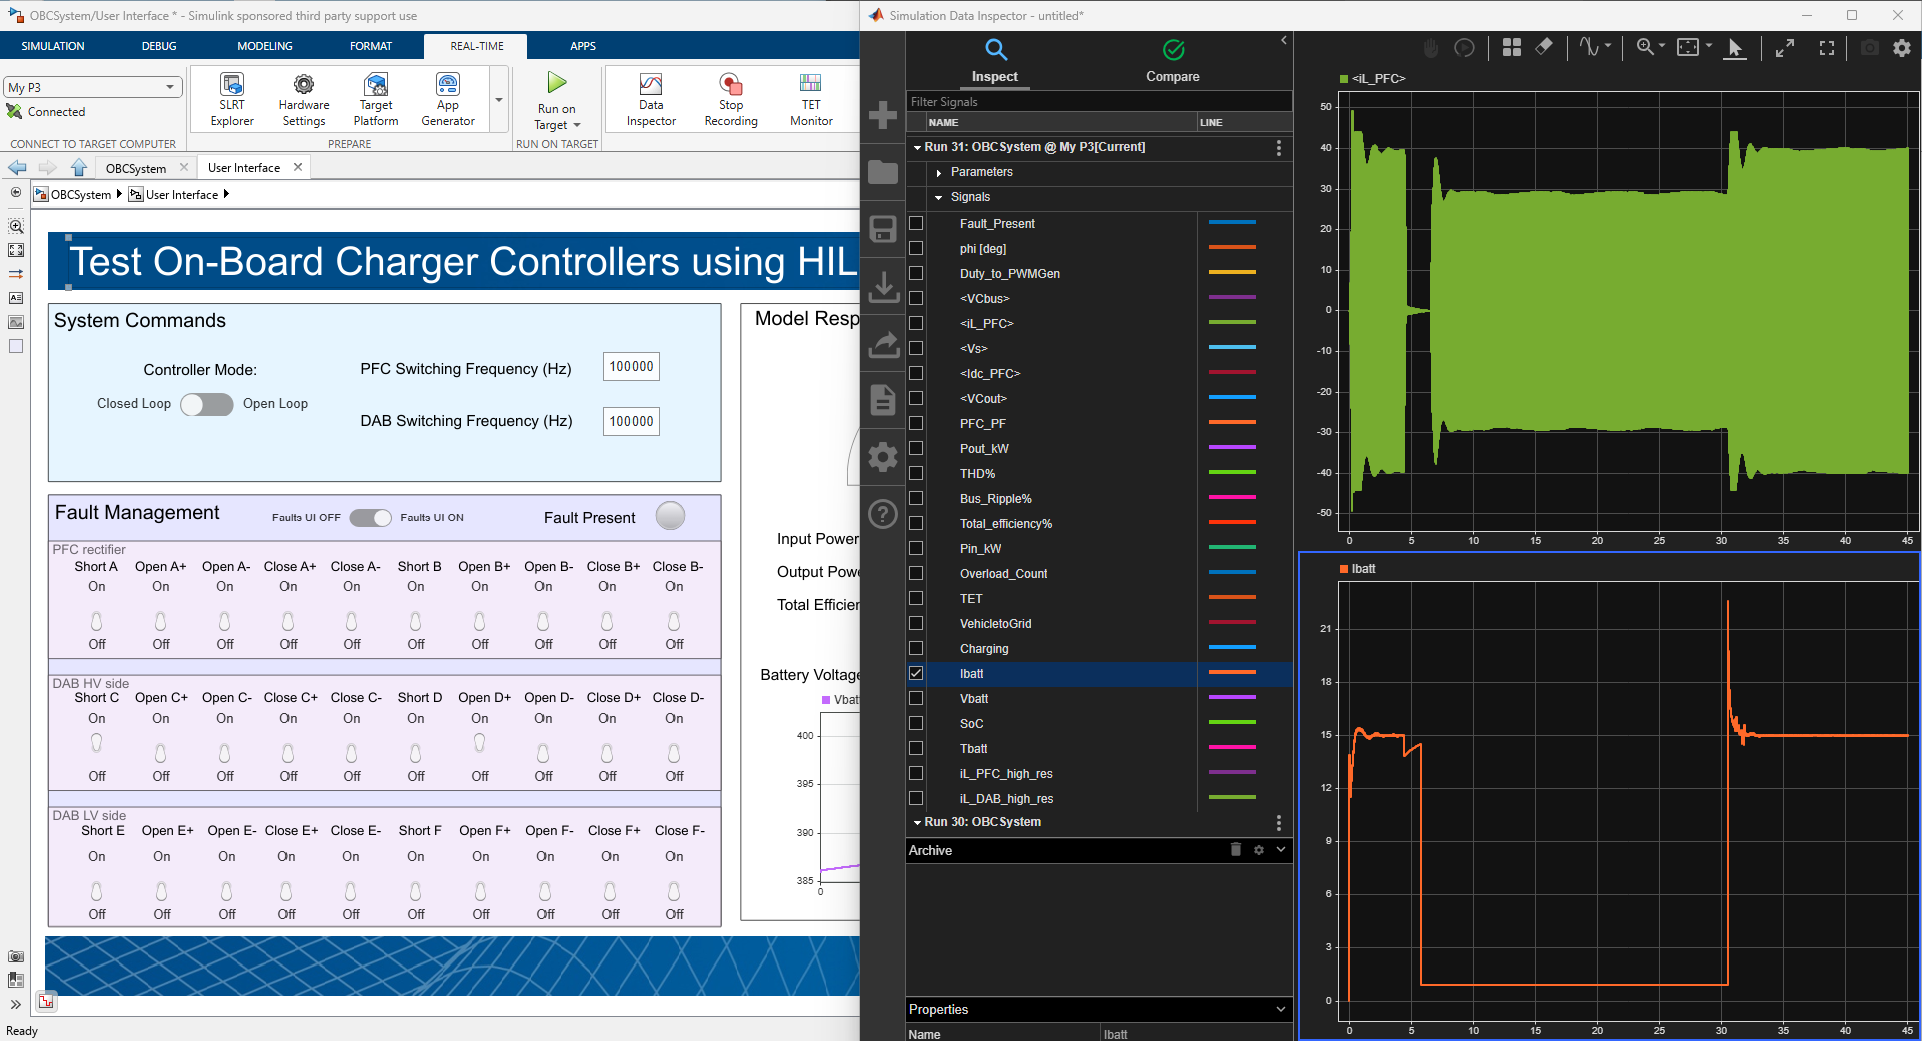

Fault injection in the DAB high-voltage bridge of an on-board charger: a short-circuit fault (Short C) and an open-switch fault (Open D+) are applied, causing a sharp reduction in DAB power transfer, battery charging current to drop from ~15 A to ~1 A, and battery voltage growth to stall until the faults are removed.

## Release Notes

For version history, updates, and known issues related to this example, see the accompanying *README.md* file.

open README.md